# Run Analysis on Synthetic Data

This notebook walks through a simplified version of the entire thesis. The idea is to create a dummy dataset to run the analysis - in the process of which we demonstrate how the analysis works. 

clear
close

### Setting up the experiment

In this section, we create an experiment object, in which we setup some parameters of the phantom data. One of the contributions of this paper is a table of $\lambda$ values that is parameterized on the number of fibers, the b-values, SNR and the order of the spherical harmonics model that's used. The $\lambda$ is computed per b-value (shell) and all of these parameters are stored in the `csaodfExperiment` object. 

expt = csaodfExperiment;
expt.fibers = 2;
expt.bvals = [1000, 3000, 4000];
expt.SNR = 50;
expt.order = 4;

% order 8 is way too descriptive. 4 is good!
for x = 1:numel(expt.bvals)
    expt.lambda(x) = getLambda(expt.fibers, expt.bvals(x), expt.SNR, expt.order);
end

% Experimentally computed weights for Laplace Beltrami regularization
expt.lambda

ans =     0.0015    0.0007    0.0015


### Generate synthetic data (from a phantom model)

% Create objects to hold gradient table
gt = gradientTable;

Next, we create a gradient table. This can be generated and downloaded from [http://www.emmanuelcaruyer.com/WebApp/q-space-sampling.php?nbPoints=300&nbShells=3&alpha=2](http://www.emmanuelcaruyer.com/WebApp/q-space-sampling.php?nbPoints=300&nbShells=3&alpha=2) or, can be read from a pre-downloaded text file called '`samples3SH.txt`'.

gt.readFromTxt('samples3SH.txt', expt.bvals);        

Now create synthetic data using some known orientations and angles to test if this kind of a reconstruction works. To keep things simple, we create a single voxel, with 300 samples computed in Q-space. We then attempt to reconstruct the spherical harmonic coefficients associated with these samples - depending on the order of the reconstruction used. 

diffData = createDiffusionData;
diffData.make(expt.fibers, gt.bValues, expt.SNR, gt.shellInd, gt.table, pi/3);

ndirs = size(gt.table, 1);
v = volume;
v.imageData = zeros(1, 1, 1, ndirs);
v.imageData(1,1,1,:) = diffData.data;

### Compute Spherical Harmonics transformation matrix

Using the gradient directions from the table above, we can then compute the spherical harmonics transformation matrix can be computed. The inputs necessary are the table and the order of the harmonics.

SH = sphericalHarmonicsMatrix;
SH.make(gt.table, expt.order, 0);

### Process the volume!

Finally, we process the volume - meaning we reconstruct the spherical harmonics coefficients using the linear transformation we computed earlier, so that there's no need to do the full funk radon transform, thereby improving computation time by > 15x, and, also constructing a resonable estimation of the fiber orientation using a model-based method.

shCoeff = expt.processVolume(v, gt, SH);

Processing voxel (  1,  1,  1) ...................... Done!


### Visualize the reconstruction

To make more sense of how this looks like, we plot the Orientation Distribution Function and observe how it looks.

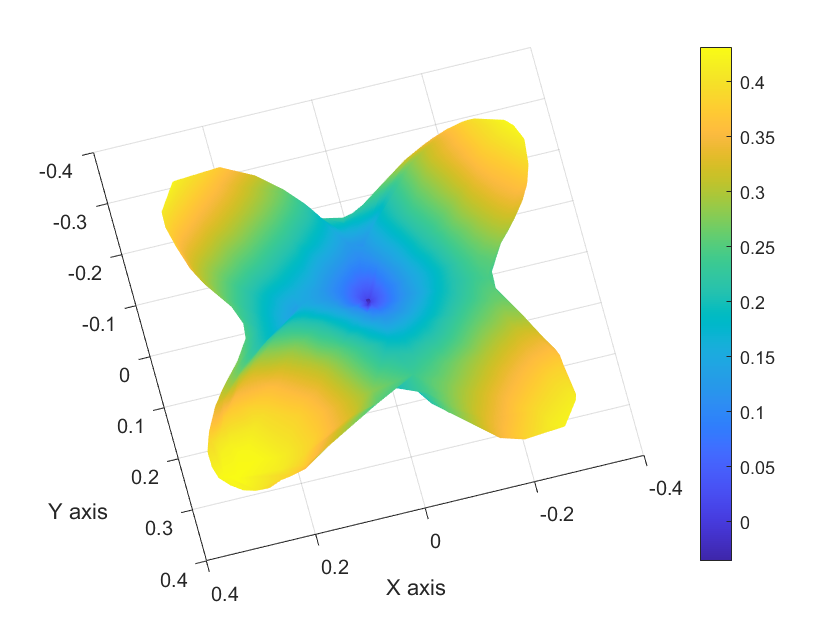

% Retrieve coefficients estimated
shData = shCoeff.getValues(1,1,1,0,0);

% Choose a large number of uniform points for smoother visualization.
points = genNSpherePoints(1000);

% Reconstruct data from coefficients
SHviz = sphericalHarmonicsMatrix;
SHviz.make(points, expt.order, 0);
reconstructedData = SHviz.getData(shData);

% Visualize reconstruction.
expt.visualizeODF(reconstructedData, points);